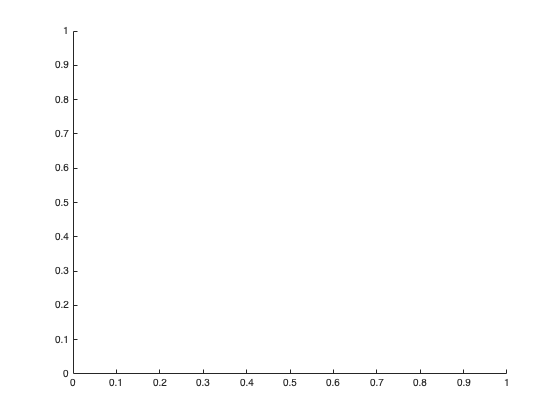

%%%% Author: Anson Li
%%%% Email: ting.h.li@mail.mcgill.ca
close all; clf; clc; cla;

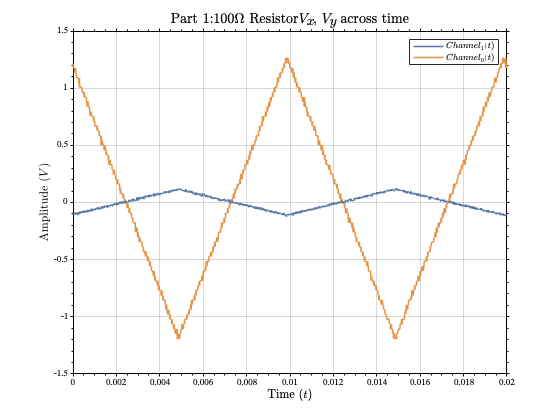

working_directory = './part-1/';
input_csv_filename = '1-TRIANGLE-100-OHMS-WAVE.csv';

SignalName = '$100\Omega$ Resistor';
PlotTitle = strcat('Part 1:  ',SignalName);
bandlimit = 500;


% output directory
out_directory = 'out/';
if ~exist(strcat(working_directory,out_directory),'dir')
    mkdir(strcat(working_directory,out_directory))
end
imageResolution = 600;

% output file name computations
output_pdf_filename = [input_csv_filename(1:end - 4), '.pdf'];
output_png_filename = [input_csv_filename(1:end-4),'-plotted.png'];

% Load Data from CSV
InputData = readmatrix(strcat(working_directory,input_csv_filename));

% Oscilloscope Timestep
sampling_interval = 8 * 10^(-6); % seconds

% time vector
dataLength=size(InputData,1);
t = 0:sampling_interval:(dataLength-1)*sampling_interval;

% grab the channels 
% REMARK: Correspondence of Channels
% Green channel on osc. is channel0 here,
% while the blue channel on osc. is channel1
channel0 = InputData(:, 4); channel1 = InputData(:,8);

% OSCILLOSCOPE PLOT of the two channels
% Plotting the osc. in matlab

%%%%%
%%%%%
%%%%

figure(1);
hold on;
plot(t, channel0, 'DisplayName', '${Channel}_0(t)$');
plot(t, channel1, 'DisplayName', '${Channel}_1(t)$');
title([PlotTitle, '$V_x$, $V_y$', ' across time'], 'interpreter', 'latex');
legend('Interpreter', 'latex');

xlabel('Time ($t$)', 'Interpreter', 'latex');
ylabel('Amplitude ($V$)', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf, 'small');
hold off;
print(gcf, strcat(working_directory,out_directory,output_pdf_filename), '-vector', '-dpdf', '-bestfit');
exportgraphics(gcf, strcat(working_directory,out_directory,output_png_filename),'Resolution',imageResolution);


%%%%%
%%%%%
%%%%%



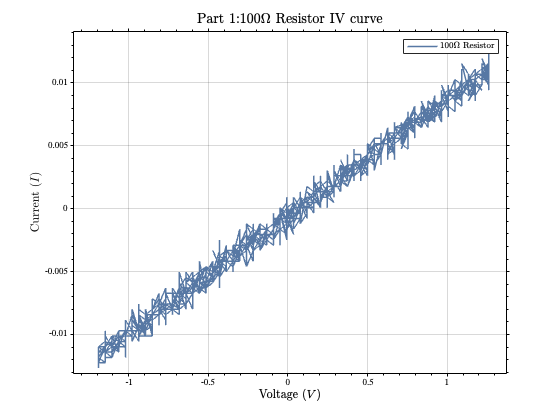

% Divide by negative 10 Ohms to obtain the current


% sometimes we want to do calculations with the channels, so we plot
% signal0, 1 instead of channel 0,1

signal0=channel0; 
signal1 = channel1./(-10);

% signal1 is the current, see above

% IV curve output file name computations
iv_output_pdf_filename = [input_csv_filename(1:end-4), '-IV.pdf'];
iv_output_png_filename = [input_csv_filename(1:end-4), '-IV-plotted.png'];
iv_output_csv_filename = [input_csv_filename(1:end-4), '-IV.csv'];

% make table and save table for iv curve
iv_table = table(signal0,signal1);
writetable(iv_table, strcat(working_directory,out_directory,iv_output_csv_filename));

%%%%%
%%%%%
%%%%%
% Plot the iv curve
figure(2);
hold on;
plot(signal0,signal1,'DisplayName', SignalName);
title([PlotTitle,' IV curve'], 'interpreter', 'latex');
legend('Interpreter','latex');

xlabel('Voltage ($V$)', 'Interpreter', 'latex');
ylabel('Current ($I$)', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf,'small');

hold off;

% print to pdf and png
print(gcf, strcat(working_directory,out_directory,iv_output_pdf_filename), '-vector', '-dpdf', '-bestfit');
exportgraphics(gcf, strcat(working_directory,out_directory,iv_output_png_filename),'Resolution',imageResolution);


%%%%%
%%%%%
%%%%%

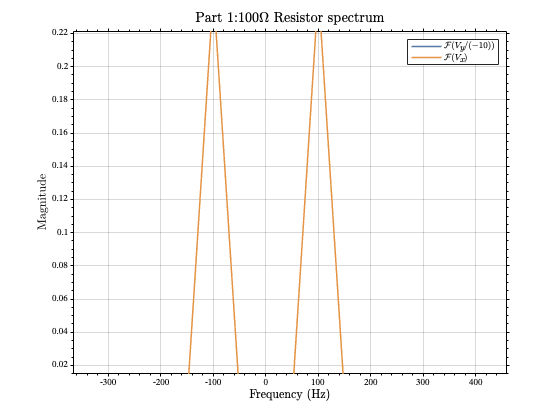

%%% SPECTRUM CALCULATIONS
% Frequency and Period of Channel 0?
% see SIG_INFO.m in MATLAB_DEFAULTS for how the following function is
% defined.
[rms0,bfreq0,pVector0,fVector0]=SIG_INFO(signal0,sampling_interval);
[rms1,bfreq1,pVector1,fVector1]=SIG_INFO(signal1,sampling_interval);

% range of the spectrum is 1/sampling_interval / 2 = [-62.5k, +62.5k]
% spectrum filename
spectrum_output_pdf_filename = [input_csv_filename(1:end-4), '-SPEC.pdf'];
spectrum_output_png_filename = [input_csv_filename(1:end-4), '-SPEC-plotted.png'];
spectrum_output_csv_filename = [input_csv_filename(1:end-4), '-SPEC.csv'];

%%%%%
%%%%%
%%%%%
% Plot Spectrum over [-bandlimit, +bandlimit]
figure(3);
hold on;
plot(fVector0,pVector0,'DisplayName','$\mathcal{F}(V_x)$');
plot(fVector1,pVector1,'DisplayName','$\mathcal{F}(V_y/(-10))$');
legend('Interpreter','latex');

xlim([-bandlimit,+bandlimit]); % lock frequency range

title([PlotTitle, ' spectrum'], 'interpreter', 'latex');
xlabel('Frequency (Hz)', 'Interpreter', 'latex');
ylabel('Magnitude', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf,'small');

print(gcf, strcat(working_directory,out_directory,spectrum_output_pdf_filename), '-vector', '-dpdf', '-bestfit');
exportgraphics(gcf, strcat(working_directory,out_directory,spectrum_output_png_filename),'Resolution',imageResolution);

%%%%%
%%%%%
%%%%%

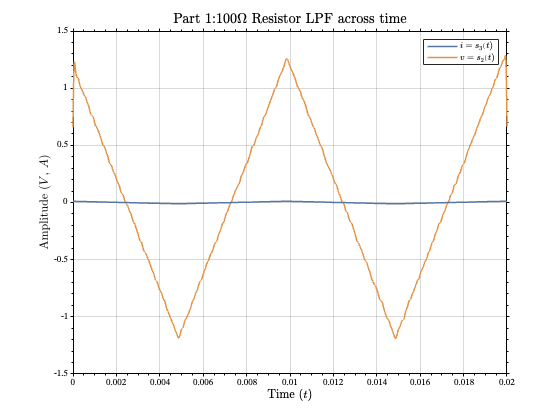

% use LPF to clean up the plots and IV curve
% try apply LPF, minimum of 5kHz 
signal2=lowpass(signal0,min(bandlimit*4, 5000), 1/sampling_interval);
signal3=lowpass(signal1,min(bandlimit*4, 5000), 1/sampling_interval);

% LPF filenames
lpf_output_pdf_filename = [input_csv_filename(1:end-4), '-LPF.pdf'];
lpf_output_png_filename = [input_csv_filename(1:end-4), '-LPF-plotted.png'];
lpf_output_csv_filename = [input_csv_filename(1:end-4), '-LPF.csv'];

lpf_iv_output_pdf_filename = [input_csv_filename(1:end-4), '-LPF-IV.pdf'];
lpf_iv_output_png_filename = [input_csv_filename(1:end-4), '-LPF-IV-plotted.png'];
lpf_iv_output_csv_filename = [input_csv_filename(1:end-4), '-LPF-IV.csv'];


% plot lpf
figure(4);
hold on;
plot(t, signal2, 'DisplayName', '$v=s_2(t)$');
plot(t, signal3, 'DisplayName', '$i=s_3(t)$');
title([PlotTitle,' LPF across time'], 'interpreter', 'latex');
legend('Interpreter', 'latex');

xlabel('Time ($t$)', 'Interpreter', 'latex');
ylabel('Amplitude ($V$, $A$)', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf, 'small');
hold off;


print(gcf, strcat(working_directory,out_directory,lpf_output_pdf_filename), '-vector', '-dpdf', '-bestfit');
exportgraphics(gcf, strcat(working_directory,out_directory,lpf_output_png_filename),'Resolution',imageResolution);

%%%%%
%%%%%
%%%%%

% IV curve after LPF?
% IV curve output file name computations
iv_output_pdf_filename = [input_csv_filename(1:end-4), '-IV.pdf'];
iv_output_png_filename = [input_csv_filename(1:end-4), '-IV-plotted.png'];
iv_output_csv_filename = [input_csv_filename(1:end-4), '-IV.csv'];

% make table and save table for iv curve
lpf_iv_table = table(signal2,signal3);
writetable(lpf_iv_table, strcat(working_directory,out_directory,lpf_iv_output_csv_filename));


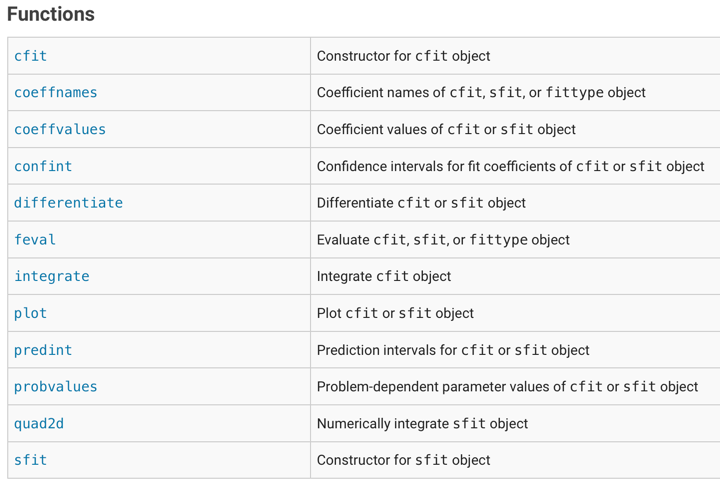

LinFitIV = fit(signal2,signal3,'poly1') % linear fit param, for exp. fit try 'exp1'

LinFitIV =      Linear model Poly1:
     LinFitIV(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =    0.009284  (0.009273, 0.009295)
       p2 =  -0.0006083  (-0.0006159, -0.0006007)

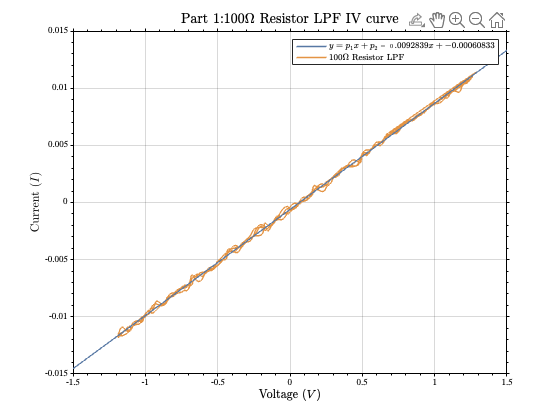

figure(5);
hold on;
plot(signal2,signal3);
plot(LinFitIV);
LinFitLabel = [num2str(LinFitIV.p1),'x + ',num2str(LinFitIV.p2)];
title([PlotTitle,' LPF IV curve'], 'interpreter', 'latex');

legend([SignalName, ' LPF'], ...
    ['$y=p_1x + p_2=',LinFitLabel,'$'], ...
    'interpreter','latex');

xlabel('Voltage ($V$)', 'Interpreter', 'latex');
ylabel('Current ($I$)', 'Interpreter', 'latex');
grid on;

STANDARDIZE_SCOPE_WITH_SUBPLOTS(gcf);
RESIZE_FIGURE(gcf,'small');

hold off;
print(gcf, strcat(working_directory,out_directory,lpf_iv_output_pdf_filename), '-vector', '-dpdf', '-bestfit');
exportgraphics(gcf, strcat(working_directory,out_directory,lpf_iv_output_png_filename),'Resolution',imageResolution);

Fitting for anonymous functions